clc; clear; close all;

% Parámetros del sistema
V_pfr = 150; % Volumen del PFR en litros
n = 10; % Número de CSTR en serie
V_cstr = V_pfr / n; % Volumen de cada CSTR

% Constantes de reacción
k = 0.1; % Constante cinética de primer orden

% Flujo de entrada
F_A = 1; % Flujo inicial de A en mol/h
F_B = 1; % Flujo inicial de B en mol/h

% Matrices de estado para n CSTR en serie
A = -k * eye(n);
B = (1/V_cstr) * ones(n,1);
C = ones(1,n); % Ajuste de la salida para compatibilidad
D = 0;

% Crear función de transferencia del sistema
sys = ss(A, B, C, D);
G = tf(sys);

% Mostrar función de transferencia sin control
disp('Función de transferencia sin control:');

Función de transferencia sin control:


G

G =
 
  0.6667 s^9 + 0.6 s^8 + 0.24 s^7 + 0.056 s^6 + 0.0084 s^5 + 0.00084 s^4 + 5.6e-05 s^3 + 2.4e-06 s^2 + 6e-08 s + 6.667e-10
  ------------------------------------------------------------------------------------------------------------------------
   s^10 + s^9 + 0.45 s^8 + 0.12 s^7 + 0.021 s^6 + 0.00252 s^5 + 0.00021 s^4 + 1.2e-05 s^3 + 4.5e-07 s^2 + 1e-08 s + 1e-10
 
Continuous-time transfer function.


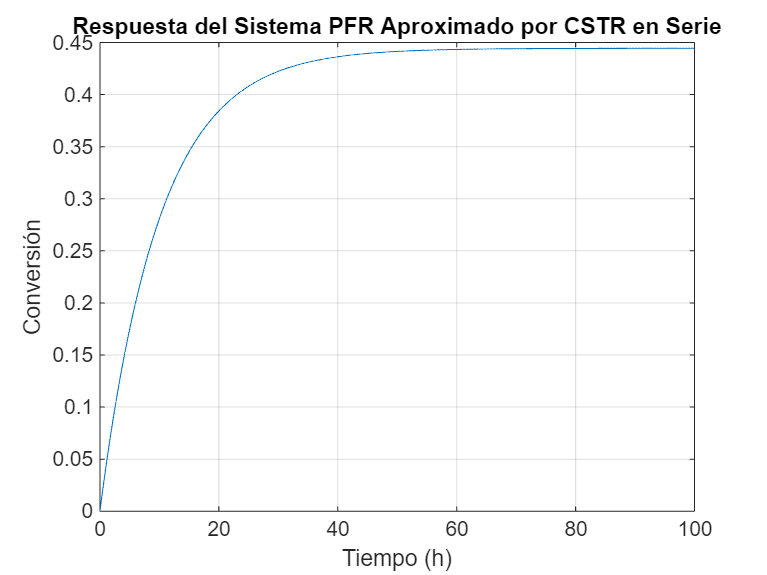


% Representación en el tiempo
t = linspace(0, 100, 1000); % Tiempo en horas
u = ones(size(t)); % Entrada escalón
[y, t_out] = lsim(G, u, t);

% Gráfica de respuesta en el tiempo
figure;
plot(t_out, y/15);
xlabel('Tiempo (h)'); ylabel('Conversión');
title('Respuesta del Sistema PFR Aproximado por CSTR en Serie');
grid on;

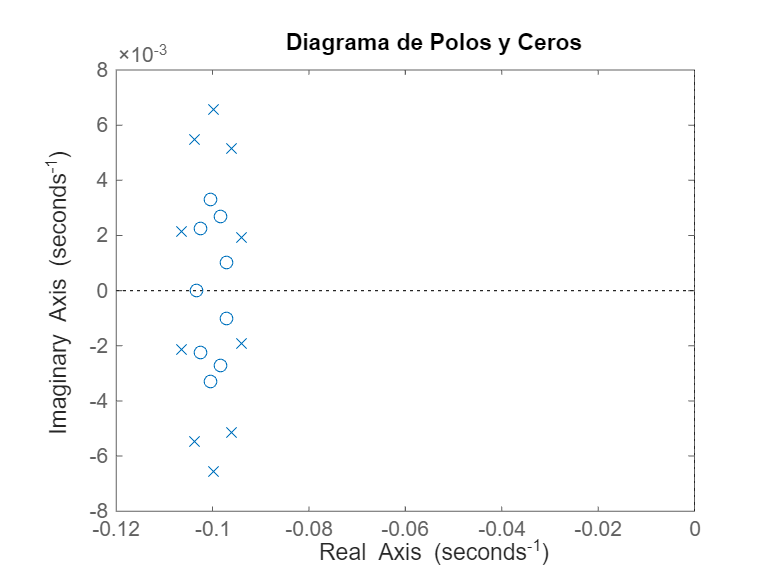


% Diagrama de polos y ceros
figure;
pzmap(G);
title('Diagrama de Polos y Ceros');


% Sintonización del control PID
Kp = 10; Ki = 5; Kd = 0.1; % Ajuste para estabilización en 0.8
PID = pid(Kp, Ki, Kd);
G_PID = feedback(PID * G, 1, -1); % Ajuste para compatibilidad de tamaños

% Mostrar función de transferencia con control PID
disp('Función de transferencia con control PID:');

Función de transferencia con control PID:


G_PID

G_PID =
 
  0.06667 s^11 + 6.727 s^10 + 9.357 s^9 + 5.406 s^8 + 1.761 s^7 + 0.3641 s^6 + 0.05041 s^5 + 0.00476 s^4 + 0.000304 s^3 + 1.26e-05 s^2 + 3.067e-07 s + 3.333e-09
  ---------------------------------------------------------------------------------------------------------------------------------------------------------------
  1.067 s^11 + 7.727 s^10 + 9.807 s^9 + 5.526 s^8 + 1.782 s^7 + 0.3666 s^6 + 0.05062 s^5 + 0.004772 s^4 + 0.0003045 s^3 + 1.261e-05 s^2 + 3.068e-07 s + 3.333e-09
 
Continuous-time transfer function.


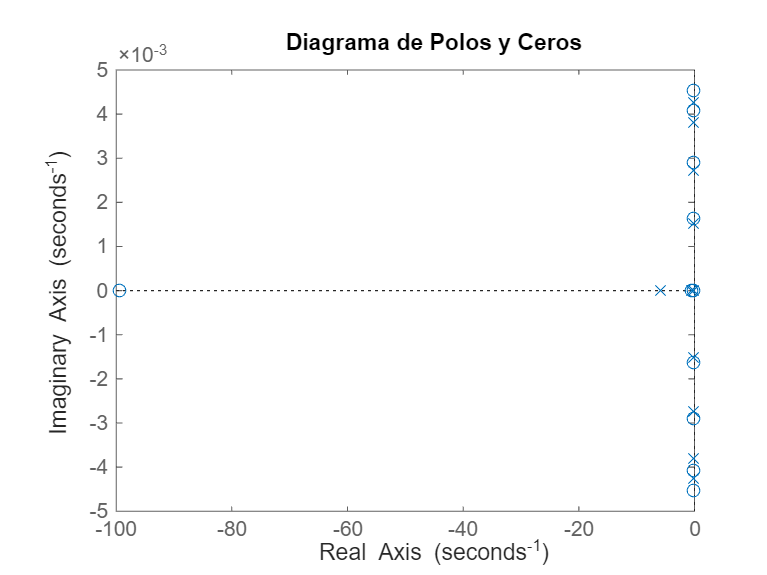

pzmap(G_PID);
title('Diagrama de Polos y Ceros');

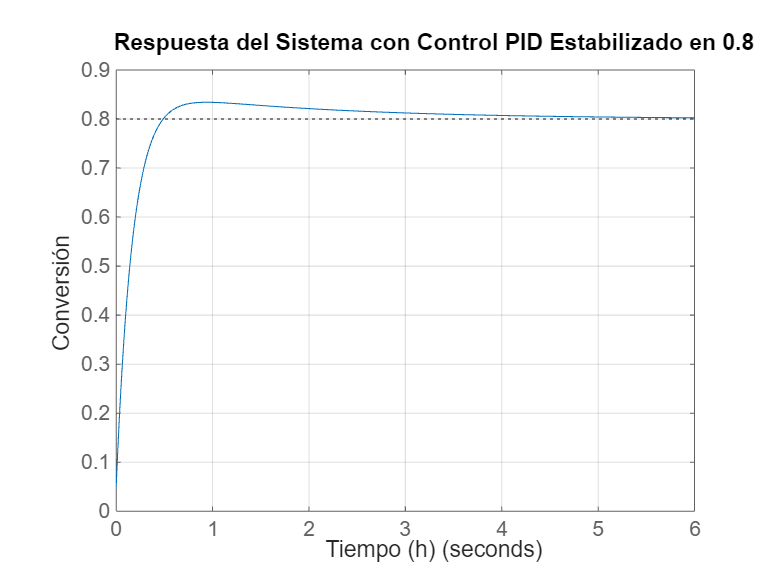


% Respuesta del sistema en lazo cerrado
y_target = 0.8; % Objetivo de estabilización
figure;
step(y_target * G_PID);
title('Respuesta del Sistema con Control PID Estabilizado en 0.8');
xlabel('Tiempo (h)'); ylabel('Conversión');
grid on;

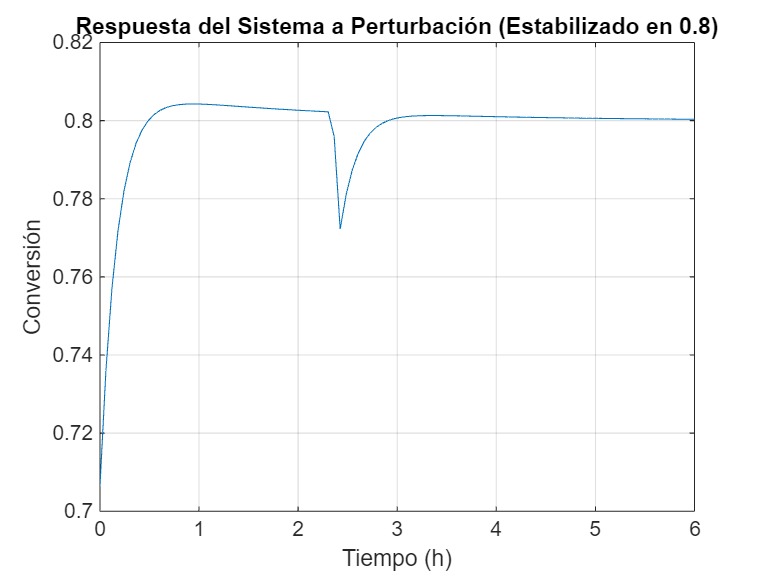


% Inserción de perturbación
t = linspace(0, 6, 100);
t_pert = t(40); % Tiempo en horas en que ocurre la perturbación
mag_pert = 0.1; % Magnitud de la perturbación
delta_u = zeros(size(t));
delta_u(t ~= t_pert) = mag_pert;

[y_pert, t_out] = lsim(G_PID, delta_u, t);

y_pert = y_pert - mag_pert;
figure;
plot(t_out, y_pert + y_target);
title('Respuesta del Sistema a Perturbación (Estabilizado en 0.8)');
xlabel('Tiempo (h)'); ylabel('Conversión');
grid on;